%%%% HW 1

## Problem 12c - w/ new Type III BC

Engs105, W24 - Prof. Paulsen

### Numerical Solution

#### Range of A

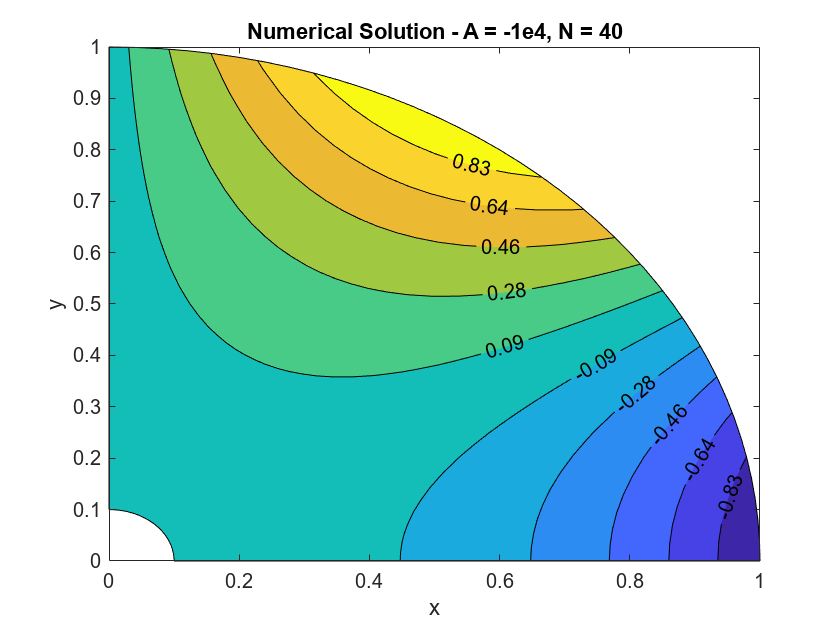

clear; close all
% Parameters
a = 0.1;
R = 1;
th_final = pi/2;
b = a^6;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = -1e4
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("-10000.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = -1e4, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA1.png', 'Resolution',300)

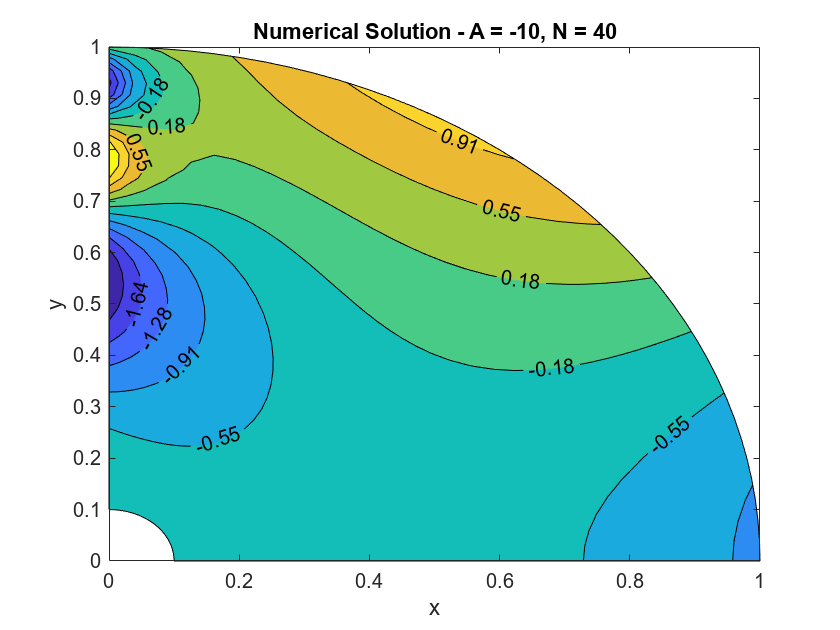


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = -10
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("-10.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = -10, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA2.png', 'Resolution',300)

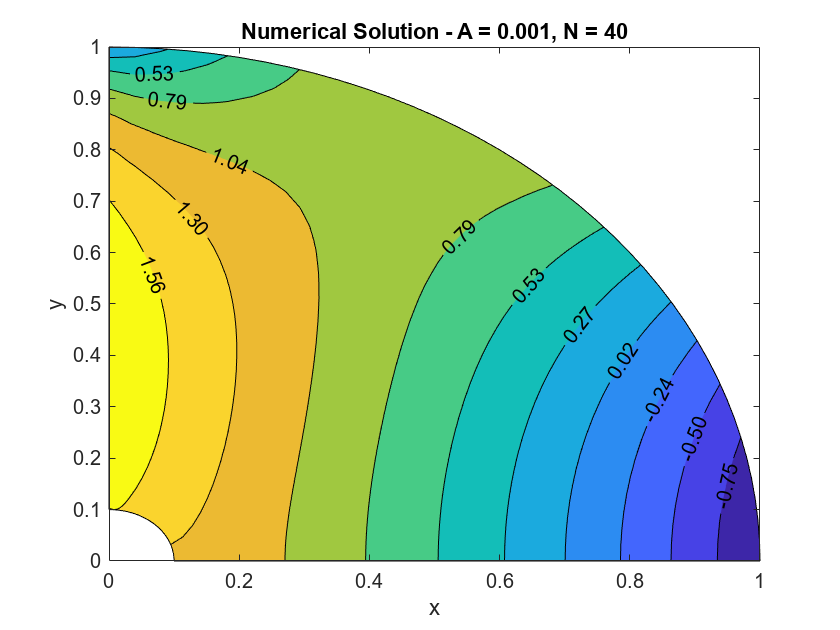


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = 0.001
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("991.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = 0.001, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA3.png', 'Resolution',300)

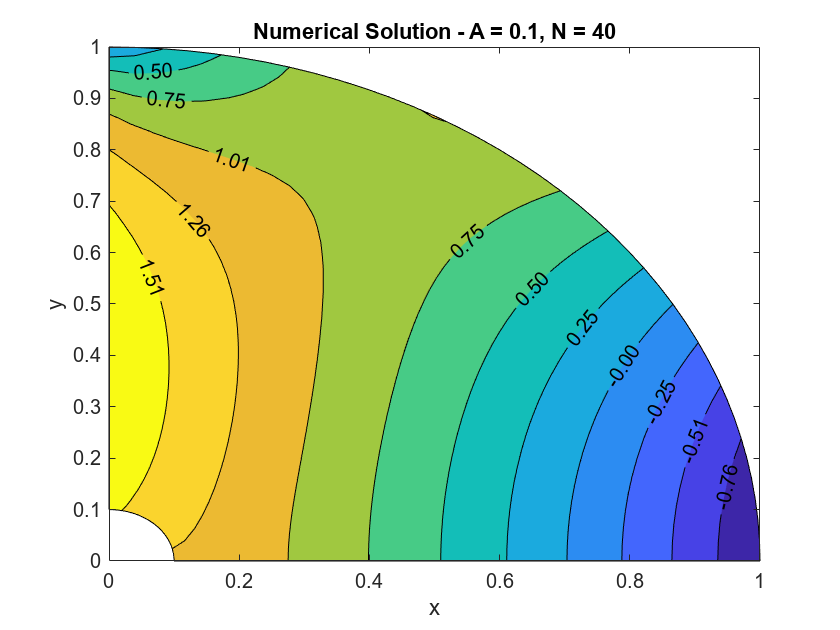


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = 0.1
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("91.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = 0.1, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA4.png', 'Resolution',300)

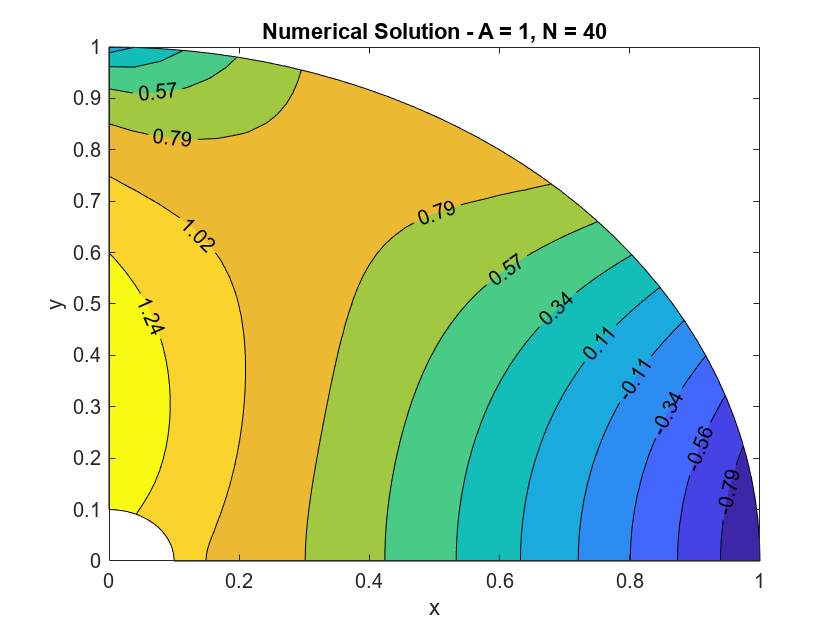


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = 1
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("11.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = 1, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA5.png', 'Resolution',300)

X_test_vector = readmatrix("11.txt");
diff = X_test_vector - X_vector;

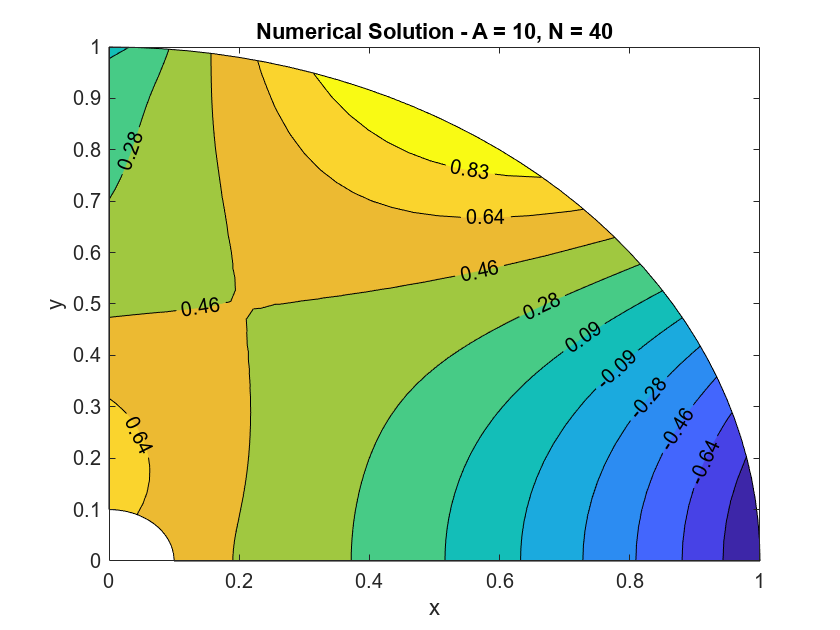


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = 10
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("10.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = 10, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA6.png', 'Resolution',300)

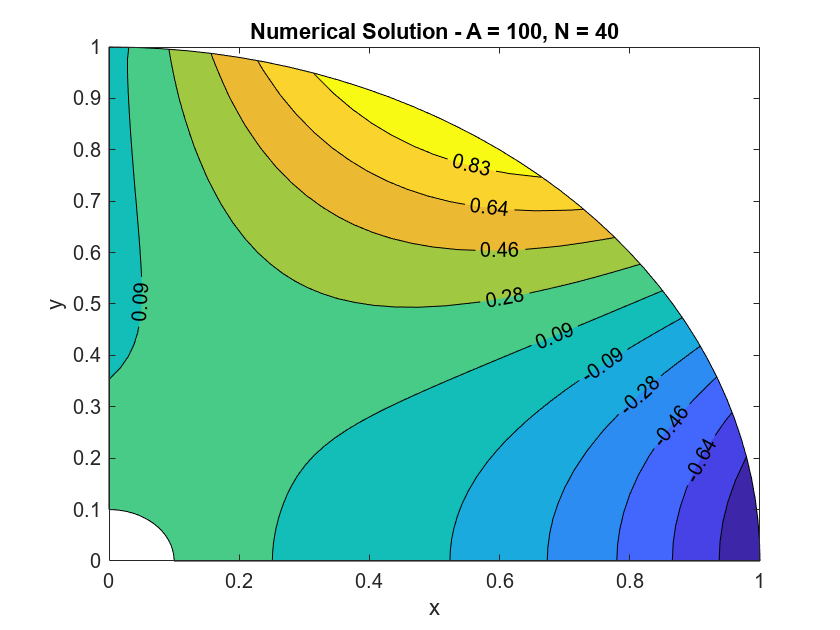


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = 100
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("100.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = 100, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA7.png', 'Resolution',300)

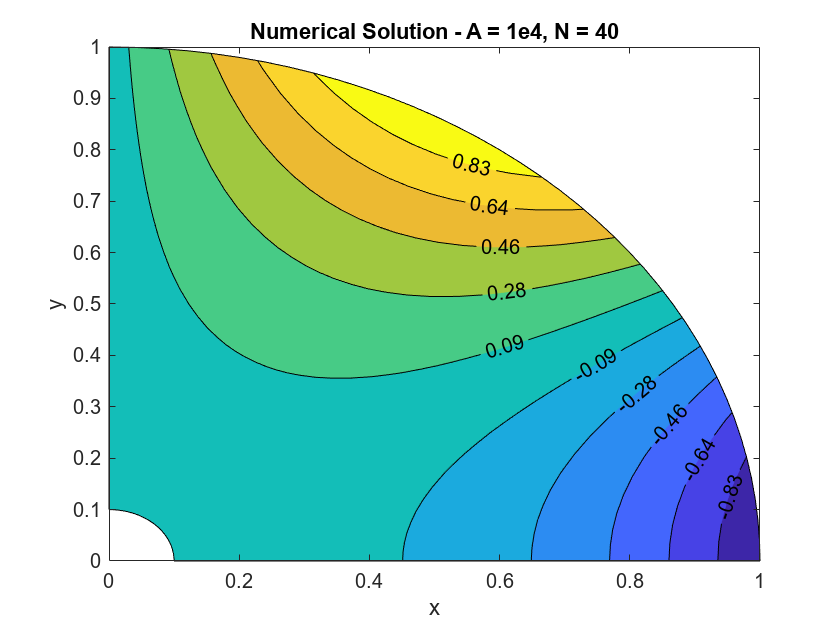


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = 1e4
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("10000.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = 1e4, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA8.png', 'Resolution',300)

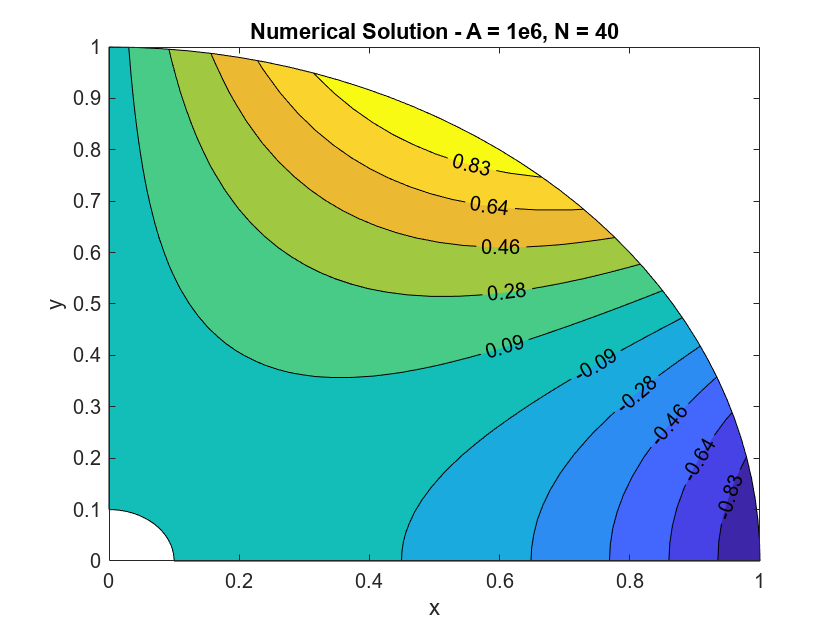


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = 1e6
N = 40;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("1000000.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = 1e6, N = 40')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineA9.png', 'Resolution',300)

%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));

Unrecognized function or variable 'U'.

figure(error_fig)
subplot(1, 3, 2)
[C, h] = contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.3f", "ShowText","on", "LabelSpacing",2000);
clabel(C, h, "FontSize", 8)
colormap(flipud(hot))
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 10')
axis square;
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);
secondPos = get(gca, 'Position');
%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)


#### N = 80

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 80
N = 80;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("80.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.3f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 80')
xlabel('x')
ylabel('y')
%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)

%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));
figure
[C, h] = contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.4f", "ShowText","on",  "LabelSpacing",2000);
clabel(C, h, "FontSize", 8)
colormap(flipud(hot))
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 80')
axis square;
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);

#### N = 200

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 200
N = 200;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("200.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.3f",  "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 200')
xlabel('x')
ylabel('y')
%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)

%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));
figure
[C, h] = contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.4f", "ShowText","on",  "LabelSpacing",2000);
clabel(C, h, "FontSize", 8)
colormap(flipud(hot))
colorbar
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 200')
axis square;
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);
%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution', 300)


### RMS Error v/s Delta R

nrange = [5, 10, 20, 40, 80, 100, 120, 160, 200];
rms_error = zeros([size(nrange), 1]);
for i = 1:length(nrange)
    filename = sprintf('%d.txt', nrange(i));
    data = readmatrix(filename);
    rms_error(i) = rms(data, 'all');
end
delrRange = (1-0.1) ./ nrange;
figure
semilogy(delrRange, rms_error, 'o-')
xlabel('$\Delta r$', 'Interpreter', 'latex')
ylabel('RMS Error')
title('RMS Error v/s $\Delta r$', 'Interpreter', 'latex');
